clear all;
close all;
clc;

% SEM HJ130G8-130S
R = 0.75;
L = 3.15e-3;
p = 8;

% Calculate model
% 4.4
beta_model = 0;
ia_model = -5:0.001:5; % armature current

n_model = [15; 25; 35];
omega_m_model = 2*pi*n_model;
omega_e_model = omega_m_model*p/2; % electric omega
lambda_m = 0.133;

% Electrical characteristics
ef_model = lambda_m * omega_e_model;
va_model = ef_model + ia_model .* (R + 1i*omega_e_model*L);

% Torque
% tf_tot = 0.001638 * omega_m + 0.4942;

tf_tot_model = 0.002401 * omega_m_model + 0.5246;
tf_pmsm_model = 0.2 * tf_tot_model;
td_model = 3*ef_model*ia_model*cos(beta_model)./omega_m_model;
ts_model = td_model - tf_pmsm_model;

% 5
PF_model = cos(angle(va_model));
% Motor
eff_model = (ts_model > 0).*(td_model > 0).*(ts_model.*omega_m_model)./abs(3*va_model.*ia_model.*PF_model);
% Generator
eff_model = eff_model + (ts_model < 0).*(td_model < 0).*abs(3*va_model.*ia_model.*PF_model)./abs(ts_model.*omega_m_model);


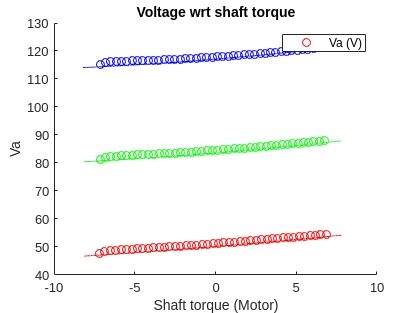

% Calculate - Actual

Ns = 43;
s = 3; % time step

load('Measurement_Data/Measurement_2023_12_14_16_46.mat');
for k = 1:1:Ns
   Ia_DCM_filtered(1, k) = mean(Ia_DCM(1600*k*s-2000-1:1600*k*s-1));
   Va_DCM_filtered(1, k) = mean(Va_DCM(1600*k*s-2000-1:1600*k*s-1));
   Ia_ACM_filtered(1, k) = mean(Ia_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   Van_ACM_filtered(1, k) = mean(Van_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   PF_ACM_filtered(1, k) = mean(PF_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   n_filtered(1, k) = mean(n(1600*k*s-2000-1:1600*k*s-1));
end

load('Measurement_Data/Measurement_2023_12_14_16_50.mat');
for k = 1:1:Ns
   Ia_DCM_filtered(2, k) = mean(Ia_DCM(1600*k*s-2000-1:1600*k*s-1));
   Va_DCM_filtered(2, k) = mean(Va_DCM(1600*k*s-2000-1:1600*k*s-1));
   Ia_ACM_filtered(2, k) = mean(Ia_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   Van_ACM_filtered(2, k) = mean(Van_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   PF_ACM_filtered(2, k) = mean(PF_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   n_filtered(2, k) = mean(n(1600*k*s-2000-1:1600*k*s-1));
end

load('Measurement_Data/Measurement_2023_12_14_16_54.mat');
for k = 1:1:Ns
   Ia_DCM_filtered(3, k) = mean(Ia_DCM(1600*k*s-2000-1:1600*k*s-1));
   Va_DCM_filtered(3, k) = mean(Va_DCM(1600*k*s-2000-1:1600*k*s-1));
   Ia_ACM_filtered(3, k) = mean(Ia_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   Van_ACM_filtered(3, k) = mean(Van_rms_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   PF_ACM_filtered(3, k) = mean(PF_ACM(1600*k*s-2000-1:1600*k*s-1)); 
   n_filtered(3, k) = mean(n(1600*k*s-2000-1:1600*k*s-1));
end


ia_meas = Ia_ACM_filtered; % armature current

omega_m_meas = 2*pi*n_filtered;
omega_e_meas = omega_m_meas*p/2; % electric omega

% Electrical characteristics
va_meas = Van_ACM_filtered.*exp(1i.*acos(PF_ACM_filtered));
ef_meas = va_meas - ia_meas.*(R + 1i.*omega_e_meas*L);

% Torque
beta_meas = angle(ef_meas);
tf_tot_meas = 0.002401 * omega_m_meas + 0.5246;
tf_pmsm_meas = 0.2 * tf_tot_meas;
td_meas = 3*abs(ef_meas).*ia_meas.*cos(beta_meas)./omega_m_meas;
ts_meas = td_meas - tf_pmsm_meas;

% 5

PF_meas = PF_ACM_filtered;
% Motor
eff_meas = (ts_meas > 0).*(td_meas > 0).*(ts_meas.*omega_m_meas)./abs(3*va_meas.*ia_meas.*PF_meas);
% Generator
eff_meas = eff_meas + (ts_meas < 0).*(td_meas < 0).*abs(3*va_meas.*ia_meas.*PF_meas)./abs(ts_meas.*omega_m_meas);

figure;
hold on;
col = ['r', 'g', 'b'];
for k=1:3
    meas(k) = plot(ts_meas(k,:), abs(va_meas(k,:)), 'o', Color=col(k));
    model(k) = plot(ts_model(k,:), abs(va_model(k,:)), Color=col(k));
end
title('Voltage wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

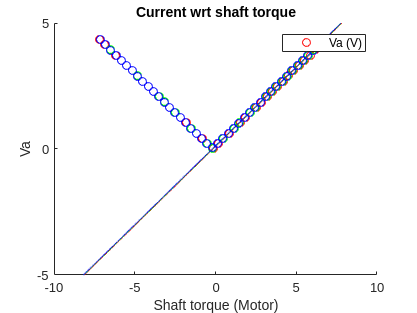


figure;
hold on;
for k=1:3
    meas(k) = plot(ts_meas(k,:), ia_meas(k,:), 'o', Color=col(k));
    model(k) = plot(ts_model(k,:), ia_model, Color=col(k));
end
title('Current wrt shaft torque');
xlabel('Shaft torque (Motor)');
ylabel('Va');
legend('Va (V)');
hold off;

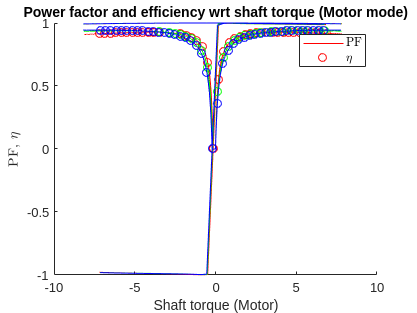


figure;
hold on;
for k=1:3
    plot(ts_meas(k,:), PF_meas(k,:), ts_meas(k,:), eff_meas(k,:), 'o', Color=col(k));
    plot(ts_model(k,:), PF_model(k,:), ts_model(k,:), eff_model(k,:), Color=col(k));
end
title('Power factor and efficiency wrt shaft torque (Motor mode)');
xlabel('Shaft torque (Motor)');
ylabel('PF, $\eta$', 'Interpreter', 'latex');
legend('PF', '$\eta$', 'Interpreter', 'latex');
hold off;